# 034IN "Fundamentals of Automatic Control" - Introduction to MATLAB  Part 7 - Nonlinear Systems 

This is the seventh MATLAB live script of the collection 034IN "Fundamentals of Automatic Control" - Introduction to MATLAB, devoted to introducing the MATLAB environment and tools for solving practical problems related to the topics of the 034IN course, i.e., performance analysis of dynamic systems, design of control law for continuous-time linear dynamical systems, approximate discretization of a continuous-time control law, etc.

Use [this link](matlab:open('./usingMATLAB_034IN.mlx')) to go back to the main live script of the collection.

##  Objectives

 The aim of this module is to understand how to create and simulate **nonlinear dynamic systems** in MATLAB. 

## Nonlinear Dynamic Systems 

### State-Space Description

A nonlinear dynamic system can be described

- by means of a set of  n-th order nonlinear ODEs, obtained exploiting some conservation balances or the mathematical description of an input/output behaviour

- using a state-space description,  i.e. a set of nonlinear first-order ODEs (the so-called state equations) and a set of algebraic equations (output equations).

- Refer to the **Part 2** of the course material, from the beginning **up to p. 19**. You mat refer also to Chapter 1 of the book [1].

In vector form, a nonlinear dynamic system can be described by **state-space equations** of the form


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& f \big(t,\, x(t),\, u(t) \big) \\
y(t) &=& g \big(t,\, x(t),\, u(t) \big)
\end{array} \right.$$


where

- $x(t)$ is the ***state*** ***vector*** with components $x_i(t),\;i=1,\,2,\,\cdots n$: $x(t) \in \mathbb{R}^n$

- $u(t)$ is the ***input*** ***vector*** with components $u_k(t),\; k=1,\,2,\,\cdots\, m$: $u(t) \in \mathbb{R}^m$

- $y(t)$ is the ***output*** ***vector*** with components $y_j(t),\; j=1,\,2,\, \cdots p$: $y(t) \in \mathbb{R}^p$

- $f(t)$ and $g(t)$ are vector-valued functions with components


$$\begin{array}{rclcrl}
f(t) &=& \big[ f_1(t)\; f_2(t)\;\cdots \; f_i(t) \; \cdots \; f_n(t) \big]^{\top} &\;& f_i\big(t,\,x_1(t),\,x_2(t),\, \cdots\,x_n(t),\, u_1(t),\, \cdots \, u_m(t) \big) & i=1,\,2,\,\cdots\, n \\ \\
g(t) &=& \big[ g_1(t)\; g_2(t)\;\cdots \; g_i(t) \; \cdots \; g_p(t) \big]^{\top} &\;&
g_j\big(t,\,x_1(t),\,x_2(t),\, \cdots\,x_n(t),\, u_1(t),\, \cdots \, u_m(t) \big) & j=1,\,2,\,\cdots\, p
\end{array}$$


Moreover, we consider assigned

- a time instant $t_0$, marked as **initial** **time** **instant**;

- a state vector $x_0$ as state at the time instant $t_0$: $x(t_0) = x_0$ (the so-called **initial** **state**);

Finally

- the **input** vector $u(t)$ is **perfectly** **known**, starting from the initial time instant $t_0$:  $u(t) \,,\;t\ge t_0$

The structure 


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& f \big(t,\, x(t),\, u(t) \big) \\
y(t) &=& g \big(t,\, x(t),\, u(t) \big)
\end{array} \right. \quad , \qquad x(t_0)=x_0\,,\quad u(t) \,,\;t\ge t_0$$


is usually called an **Initial Value Problem** (IPV) or a **Cauchy Problem**. An IPV assumes always the form


$$\dot{x}(t) = f\big(t,\,x(t), p \big)\,,\quad \dot{x}(t) = \frac{d\,x(t)}{dt}$$


where $x$ is a (vectorial) function (the solution of the ODE we are looking for) and $p$ is a vector of parameters.

### Nonlinear Systems in State-Space Form using MATLAB

Given a nonlinear dynamic system, described by a state-space representation as


$$\left\{ \begin{array}{rcl}
\dot{x}(t) &=& f \big(t,\, x(t),\, u(t) \big) \\
y(t) &=& g \big(t,\, x(t),\, u(t) \big)
\end{array} \right. \quad , \qquad x(t_0)=x_0\,,\quad u(t) \,,\;t\ge t_0 \qquad (*)$$


you can implement such a description in MATLAB by applying the following **procedure**:

- describe the IPV using the command `ode( )`;

- solve the IPV exploiting the command `solve( )`;

- compute the outputs values $y(t)$, by means of a MATLAB function implementing the output function $g\big(t,\,x(t),\, u(t) \big)\,,\; t \ge t_0$

Using this **three-step procedure** you are able

-  to describe any nonlinear system described by means of state-space equations in the form $(*)$;

- to simulate the state and the output movement, given the initial state $x(t_0)=x_0$ and the input starting from the time instant $t_0$: $u(t) \,,\;t\ge t_0$ 

## Example 1: a Double Pendulum

The double pendulum consists of two pendulums and two rigid rods. The pendulums are attached to each other, as in the following figure

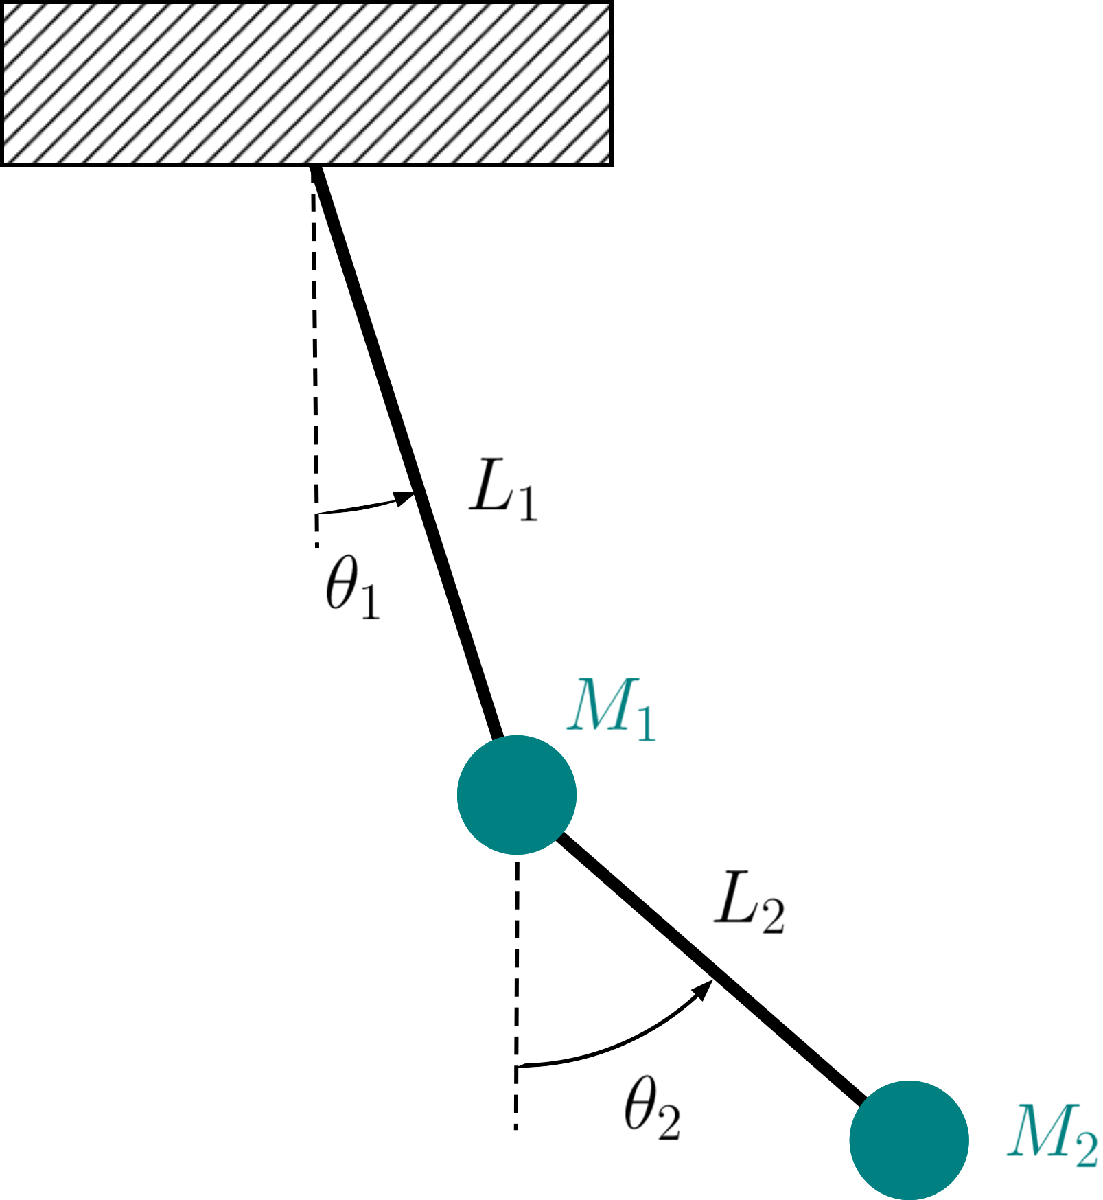

Assumptions regarding the dynamic system's model:

- the pendulum rods are massless and rigid;

- the pendulum masses are point masses;

- the only force acting on pendulums is the gravity force.

### The Model

The ODEs describing the system's motion can be derived using the direct Newtonian method (refer to [3], for example):


$$\left\{ \begin{array}{rcl}
\ddot{\theta}_1(t) &=&  \displaystyle \frac{-g\left(2M_1+M_2\right)\sin \theta_1(t)-M_2\,g\sin \big(\theta_1(t)-2\theta_2(t) \big)-2M_2\sin\big(\theta_1(t)-\theta_2(t) \big) \cdot \left[ \left(\dot{\theta}_2(t) \right)^2\cdot L_2 +  \left(\dot{\theta}_1(t) \right)^2\cdot L_1 \cos\big(\theta_1(t) - \theta_2(t) \big)\right]  }{L_1 \Big[ 2M_1+M_2-M_2 \cos\Big( 2\big(\theta_1(t) - \theta_2(t) \big) \Big) \Big]} \\ \\
\ddot{\theta}_2(t) &=&   \displaystyle \frac{2 \sin \big(\theta_1(t)-\theta_2(t) \big) \cdot \Big[ \left(\dot{\theta}_1(t) \right)^2\cdot L_1 \left(M_1+M_2\right) +
g \left(M_1+M_2\right)\cos \theta_1(t) + \left(\dot{\theta}_2(t) \right)^2 \cdot L_2\, M_2 \cos \big(\theta_1(t)-\theta_2(t) \big) \Big]}{L_2 \Big[ 2M_1+M_2-M_2 \cos\Big( 2\big(\theta_1(t) - \theta_2(t) \big) \Big) \Big]}
\end{array} \right. \qquad (\star)$$


where

- $\theta_1$ and $\theta_2$are the angles of the first and latter pendulum, respectively;

- $L_1$ and $L_2$ are the (constant) lengths of the two  rods;

- $M_1$ and $M_2$ are the (constant) masses of the pendulums;

- $g$ is the gravitational constant.

**Note**: for simplicity, it is assumed that there is **no** **input**. Gravity acceleration is NOT considered an input of the system but simply a parameter of the ODEs.

The dynamic model of the double pendulum is a set of **two second-order nonlinear Ordinary Differential Equations (ODEs)**. 

As outputs of the system consider simply:


$$\left\{ \begin{array}{rcl}
y_1(t) &=& \theta_(t) \\
y_2(t) &=& \theta_2(t)
\end{array} \right.$$


### System's Parameters

clear variables

g = 9.80665;  % Acceleration due to gravity (m/s^2)

% first set of parameters
% L1 = 1.0;  % Length of the first pendulum arm (m)
% L2 = 1.0;  % Length of the second pendulum arm (m)
% m1 = 1.0;  % Mass of the first pendulum bob [= the ball, attached to the end of the rod]  (kg)
% m2 = 1.0;  % Mass of the second pendulum bob (kg)

% a different set
L1 = 5.0;  % Length of the first pendulum arm (m)
L2 = 2.5;  % Length of the second pendulum arm (m)
m1 = 1.0;  % Mass of the first pendulum bob [= the ball, attached to the end of the rod]  (kg)
m2 = 2.0;  % Mass of the second pendulum bob (kg)

### How to Solve ODEs in MATLAB

#### **Critical Remark: from an N-th Order ODEs Set to a Set of First-Order ODEs**

 The order of the ODE equations is crucial: to be able to solve numerically in MATLAB a system of (linear or nonlinear) ODEs of order $n$ (with $n \ge 1$), we must always **rewrite** the $n$-th order ODEs set as **a set of first-order ODEs**, properly coupled each to the others. Once we have obtained the set of first-order ODEs, we can 

- describe this set using the MATLAB command `ode`, in case the ODEs are nonlinear and then solve the ODEs;

- exploit the Control System Toolbox functions (as, for example, `lsim`) in case the ODEs are describing a linear time-invariant system (refer to the [LTI Systems](matlab:open('./Intro_MATLAB_034IN_FAC_p6.mlx')) devoted live script in this collection).

#### The MATLAB Command ode

For help on using the command `ode`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `ode` command allows us to solve [Initial Value Problems (IVPs)](https://www.youtube.com/watch?v=C3WKwB5gBqI) of the form


$$\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$$


where $y$ is a (vectorial) function (the solution of the ODE we are looking for) and $p$ is a vector of parameters.

Thus, since the ODEs $(\star)$ are already a set of first-order ODEs (nonlinear ODEs), we can describe the ODEs set structure using the command `ode.`

#### Important Remark on Notation

It's not mandatory to obey the notation $\dot{y}(t) = f\big(t,\,y(t), p \big)\,,\quad \dot{y}(t) = \frac{d\,y(t)}{dt}$. Indeed, we will use a different notation for  IPVs, when they describe the evolution of a dynamic system (linear or nonlinear), keeping the notation $x$ for the state variables (the variables affected by the ODEs), and using the notation $y$ for the system's outputs. Thus, our default notation for an IVP is


$$\dot{x}(t) = f\big(t,\,x(t), p \big)\,,\quad \dot{x}(t) = \frac{d\,x(t)}{dt}$$


#### **How to Obtain a Set of First-Order ODEs **

 Given the ODEs set $(\star)$, let's **transform** it into a **set of first-order ODEs** with proper initial conditions (Refer to **Part 2 **of the course material, **pp. 16-18**.) :

- The dynamic system is mechanical; thus, the positions and velocities (linear, angular) of rigid bodies’ centres of mass are candidates for state variables.

-  The rods are massless, so the **state variables** are the **angular positions and velocitie**s of the two **masses**.


$$\left\{ \begin{array}{rcl}
x_1(t) &:= & \theta_1(t) \\
x_2(t) &:=& \displaystyle \frac{d\, \theta_1(t)}{dt} = \dot{\theta}_1(t) \\
x_3(t) &:= & \theta_2(t) \\
x_4(t) &:=& \displaystyle \frac{d\, \theta_2(t)}{dt} = \dot{\theta}_2(t) \\
\end{array} \right.$$


Using this set of variables, let's transform the Eq.s $(\star)$ into a set of first-order ODEs, i.e. a state-space description


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=&  \displaystyle  x_2(t) \\ \\
\dot{x}_2(t) &=&   \displaystyle \frac{-g\left(2M_1+M_2\right)\sin x_1(t)-M_2\,g\sin \big(x(t)-2x_3(t) \big)-2M_2\sin\big(x_1(t)-x_3(t) \big) \cdot \left[ \left(x_4(t) \right)^2\cdot L_2 +  \left(x_2(t) \right)^2\cdot L_1 \cos\big(x_1(t) -x_3(t) \big)\right]  }{L_1 \Big[ 2M_1+M_2-M_2 \cos\Big( 2\big(x_1(t) - x_3(t) \big) \Big) \Big]} \\ \\
\dot{x}_3(t) &=&  \displaystyle x_4(t) \\ \\
\dot{x}_4(t) &=& \displaystyle \frac{2 \sin \big(x_1(t)-x_3(t) \big) \cdot \Big[ \left(x_2(t) \right)^2\cdot L_1 \left(M_1+M_2\right) +
g \left(M_1+M_2\right)\cos x_1(t) + \left(x_4(t) \right)^2 \cdot L_2\, M_2 \cos \big(x_1(t)-x_3(t) \big) \Big]}{L_2 \Big[ 2M_1+M_2-M_2 \cos\Big( 2\big(x_1(t) - x(t) \big)_3 \Big) \Big]}
\end{array} \right. \qquad (*)


$$


The IVP, we would like to solve in MATLAB, is described by the Eqs $(*)$ toghether with the initial conditions


$$\left\{ \begin{array}{rcl}
x_1(t_0) &:= &\displaystyle \theta_1(t_0) = \bar{\theta}_1 \\
x_2(t_0) &:=& \displaystyle \dot{\theta}_1(t_0) = \omega_1(t_0) = \bar{\omega}_1\\
x_3(t_0) &:= & \displaystyle \theta_2(t_0) = \bar{\theta}_2\\
x_4(t_0) &:=& \displaystyle \dot{\theta}_2(t_0)  = \omega_2(t_0) = \bar{\omega}_2\\
\end{array} \right.$$


where $t_0$ is the initial time instant.

#### The IVP Initial Condtions

t0    =  0; % starting time instant [s]
tStop = 20; % end of the simulation [s]

%
barTheta1 = pi/2; % Initial angle of the first pendulum (radians)
barOmega1 = 0;    % Initial angular velocity of the first pendulum (rad/s)

barTheta2 = pi/2; % Initial angle of the second pendulum (radians)
barOmega2 = 0;    % Initial angular velocity of the second pendulum (rad/s)
%}

%{
barTheta1 = pi/2; % Initial angle of the first pendulum (radians)
barOmega1 = 0;    % Initial angular velocity of the first pendulum (rad/s)

barTheta2 = deg2rad(-10); % Initial angle of the second pendulum (radians) *** try -8 deg ***
barOmega2 = 0;    % Initial angular velocity of the second pendulum (rad/s)
%}

#### Describing the ODEs in MATLAB

%
DoublePend_ODE = ode;                               % let's initialise an ODE object
DoublePend_ODE.Parameters   = [g, L1, L2, m1, m2];  % the parameters of the differential equation
% a set of parameters
% L1  Length of the first pendulum arm (m)
% L2  Length of the second pendulum arm (m)
% m1  Mass of the first pendulum bob [= the ball, attached to the end of the rod]  (kg)
% m2  Mass of the second pendulum bob (kg)

DoublePend_ODE.InitialValue = [barTheta1, barOmega1, barTheta2, barOmega2]; % the initial conditions
DoublePend_ODE.InitialTime = t0;  % starting time instant
                                  % the initial time instant of the solution, where 
                                  % the initial conditions are applied
DoublePend_ODE.ODEFcn = @doublePEND_ODE; % doublePEND_ODE is the MATLAB function describing the ODE, 
                                         % we would like to solve. 
                                         % The code of doublePEND_ODE is at the end
                                         % of this live script.


#### Simulation of the System - Solving the ODE

Given the MATLAB description of the IVP we would solve, let's determine a numeric solution by applying the MATLAB command `solve`.

For help on using the command `solve`, and examples, refer to the [online documentation](https://it.mathworks.com/help/matlab/ref/ode.html) or execute the following piece of code in the MATLAB Command Window 

Briefly, the `solve` command computes the solution of the considered IVP `F` in the time interval `[t0, tf]`, returning the solution `S` at each time step chosen by the solver: 

S  = solve(DoublePend_ODE, t0, tStop); % solve the IPV described by F_ODE 
                           % in the time interval [t0, tf]

doubleP_x = S.Solution; % the result of the IPv: the state movement
t_stamps = S.Time;   % time instants corresponding to the solution samples 

doubleP_x1 = doubleP_x(1,:);
doubleP_x2 = doubleP_x(2,:);
doubleP_x3 = doubleP_x(3,:);
doubleP_x4 = doubleP_x(4,:);

y1 = doubleP_x1; % the model output y_1
y2 = doubleP_x3; % the model output y_2

tMIN = min(t_stamps); tMAX = max(t_stamps);

#### Retrieving and Showing the Result

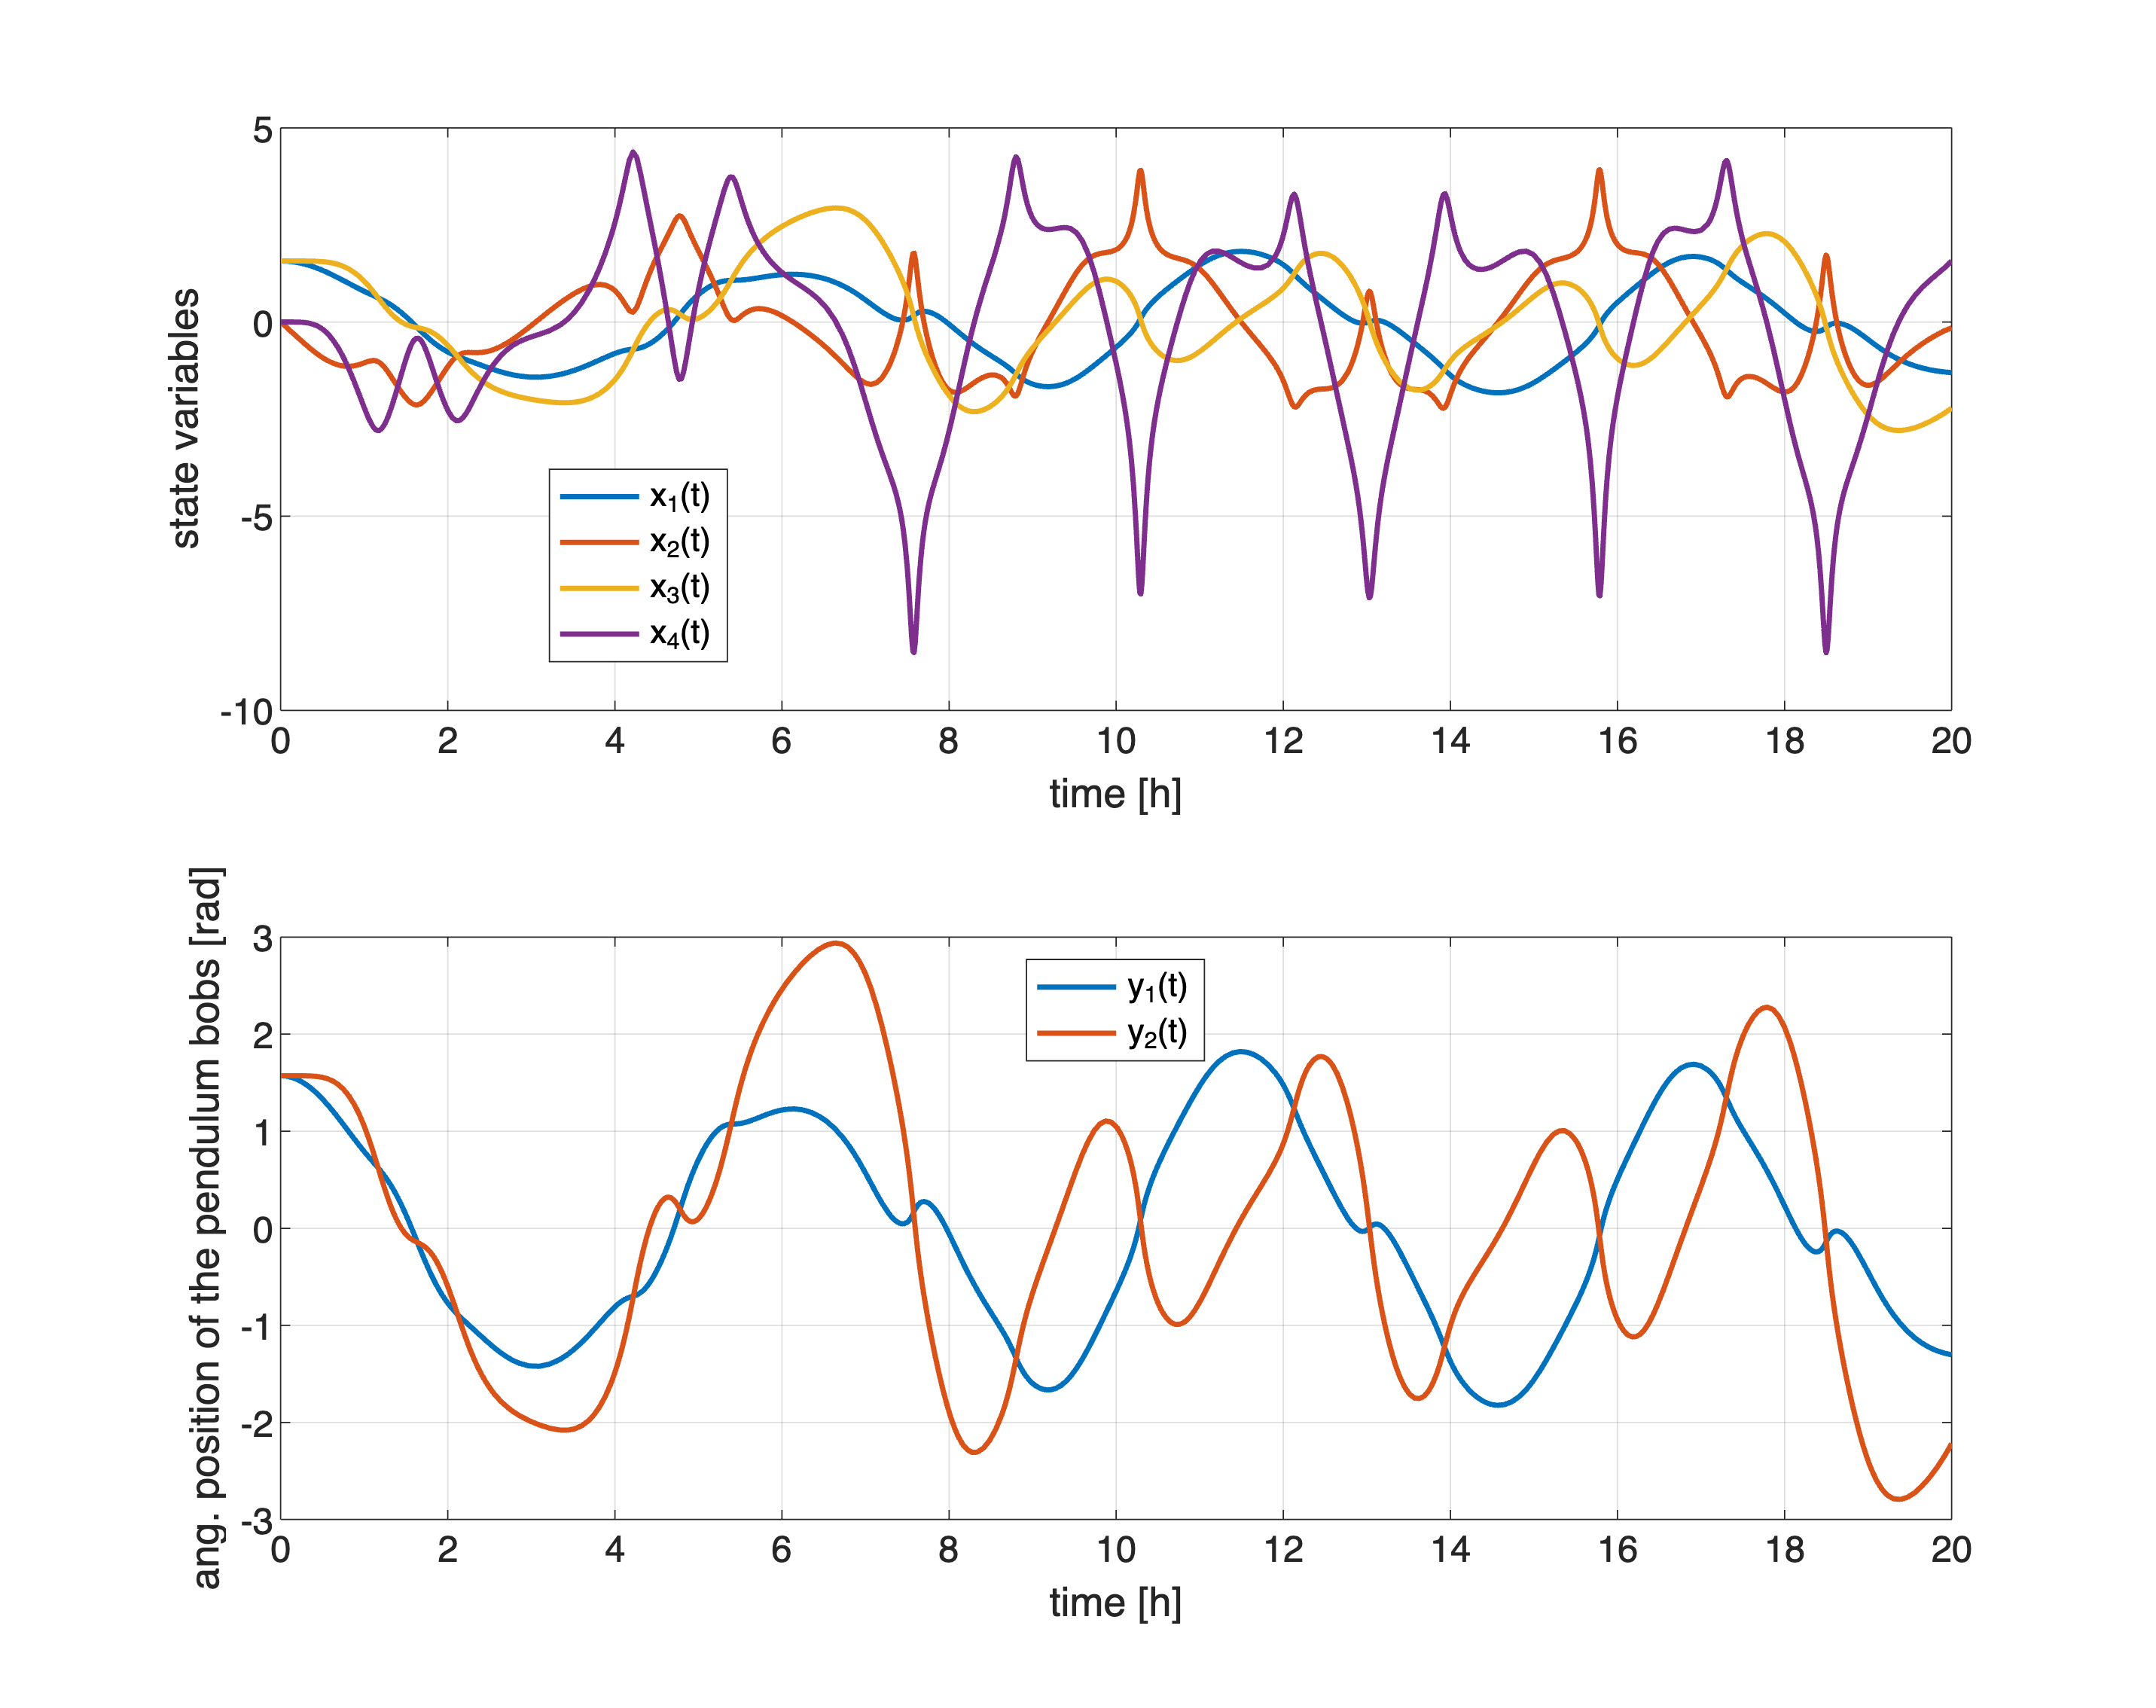

figure('Name','Double Pendulum Simulation','Units','normalized','Position',[0.1, 0.1, 0.75, 0.95]);
h1 = subplot(2,1,1);
plot(t_stamps, doubleP_x1, 'LineWidth',2); % first state variable
hold on
plot(t_stamps, doubleP_x2, 'LineWidth',2); % second state variable
plot(t_stamps, doubleP_x3, 'LineWidth',2); % third state variable
plot(t_stamps, doubleP_x4, 'LineWidth',2); % fourth state variable

xlabel('time [h]'); ylabel('state variables'); % labels on the plot axes
grid on; currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);
legend('x_1(t)', 'x_2(t)', 'x_3(t)', 'x_4(t)', 'Location', 'best')

h2 = subplot(2,1,2);
plot(t_stamps, y1, 'LineWidth',2); % double pendulum outputs y_1 vs time
hold on
plot(t_stamps, y2, 'LineWidth',2); % double pendulum outputs y_2 vs time
xlabel('time [h]'); ylabel('ang. position of the pendulum bobs [rad]'); % labels on the plot axes
grid on; 
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);
legend('y_1(t)', 'y_2(t)', 'Location', 'best')

linkaxes([h1 h2], 'x');

## Example 2: Insulin-Glucose Dynamics

Glucose is the key source of energy for all cells in the body. Numerous factors influence its levels, including body constitution, food intake, digestion, stress and exercise. Healthy individuals have sophisticated mechanisms regulating glucose concentration in the blood.

Refer to the following Figure for a schematic picture of the body parts involved:

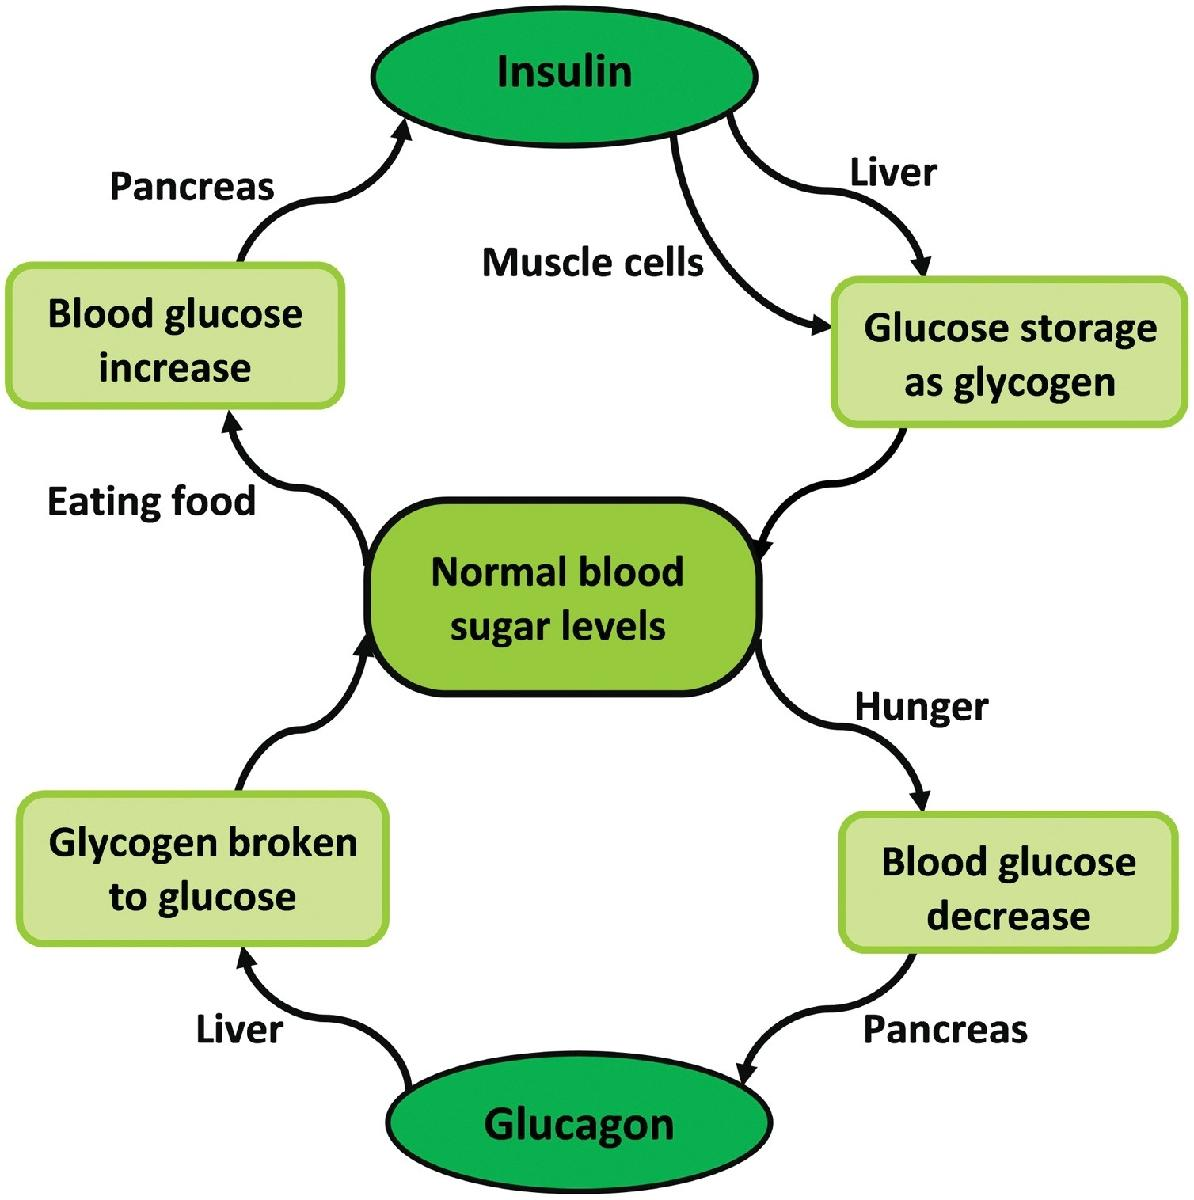

Schematic diagram of body parts involved 

in the control of glucose (image from [5]).

 The pancreas secretes two hormones: insulin and glucagon. Glucagon is released into the bloodstream when the glucose level is low. It acts on cells in the liver that release glucose. Insulin is secreted when the glucose level is high. This causes the glucose level to be lowered and the liver and other cells to take up more glucose. Other hormones influence glucose concentration.

The **blood glucose concentration** must be regulated to be in the range of 70–110 mg/L.

### The Model

The mechanisms that regulate glucose and insulin are complicated. There are different **models** of these mechanisms, some of which are simpler than others.

This model for **insulin-glucose dynamics** was described in [4] . The dynamics are described by the equations


$$\left\{ \begin{array}{rcl}
 \dot{G}_{\Delta}(t) &=& -p_1\,G_{\Delta}(t) -X(t)\,\big[G_{\Delta}(t)+G_b \big] + P(t)    \\
\dot{X}(t) &=& -p_2\,X(t) + p_3\,I_{\Delta}(t)\\
\dot{I}_{\Delta}(t) &=& -n\big[I_{\Delta}(t) + I_b \big] + \frac{u(t)}{V_I} \\
\dot{P}(t) &=& -k\,P(t)
\end{array} \right. \qquad (+)$$


where:

- $G(t)$ is the glucose concentration in the [blood plasma](https://en.wikipedia.org/wiki/Blood_plasma)  [mg/dL];

- $G_{\Delta}(t)$ represents the difference of plasma glucose concentration from the basal value $G_b$: $G_{\Delta}(t) := G(t)-G_b$;

- $I(t)$ is the insulin concentration in the [interstitial fluid](https://en.wikipedia.org/wiki/Extracellular_fluid#Interstitial_fluid)  [ $\mu$U/mL];

- $I_{\Delta}(t)$ is the difference of free plasma insulin from the basal value $I_b$: $I_{\Delta}(t) := I(t)-I_b$;

- $X(t)$ represents the increased removal rate of glucose due to insulin  [ $\text{min}^{-1}$ ];

- the term $P(t)$represents the rate glucose enters the bloodstream from intestinal absorption after a meal;

- $u(t)$ is the rate of infusion of exogenous insulin;

- $V_I$ is the insulin distribution volume;

- $n$ is the fractional disappearance rate of insulin;

- $k$ is the rate constant of glucose delivery to the blood circulatory system;

- the parameters $p_1,\,p_2$ and $p_3$ have been estimated in studies of diabetic and normal human subjects.

The model $(+)$ of the glucose-insulin dynamics is a set of **four first-order nonlinear Ordinary Differential Equations (ODEs)**. 

As output of the system consider simply:


$$ \begin{array}{rcl}
y(t) &=& G_{\Delta}(t) 
\end{array}$$


### System's Parameters

clear variables

G_b = 4.5*1e-3*180;  % basal value of glucose concentration in plasma (normal individuals) [mg/L]
% molar mass of glucose <--> 180 g
I_b = 15;   % typical concentration of basal insulin, in case of controlled diabetic 
            % subjects under steady-state conditions [mu U/mL <--> mU/L]
V_I = 12;   % typical insulin distribution volume [L]
n = 5/54;   % disappearance rate of insulin [min^(-1)]

k = 0.05;   % rate constant of glucose delivery to the blood circulatory system [min^(-1)]

% first set of parameters -- normal subjects
% p1 = 0.028;
% p2 = 0.025;
% p3 = 1.3E-5;

% a different scenario -- diabetic (glucose resistant) people
p1 = 0.0; % <<-- Note: this is the only parameter modification
p2 = 0.025;
p3 = 1.3E-5;

Simulate the model using both the set of values for the parameters $p_1, p_2$ and $p_3$.

### How to Represent the Model in MATLAB

 The ODEs set $(+)$ is a **set of first-order ODEs**, thus we have to select the state variables and then to assign proper initial conditions (Refer to **Part 2 **of the course material, **pp. 16-18**.) :

- A set of first-order ODEs describes the dynamic system; it's straightforward to select as state variables the quantities associated with the first derivative terms:


$$\left\{ \begin{array}{rcl}
x_1(t) &:= & G_{\Delta}t) \\
x_2(t) &:=& X(t) \\
x_3(t) &:= & I_{\Delta}(t) \\
x_4(t) &:=& P(t) \\
\end{array} \right.$$


Using this set of variables, let's rewrite the Eq.s $(+)$ as a state-space description


$$\left\{ \begin{array}{rcl}
 \dot{x}_{1}(t) &=& -p_1\,x_{1}(t) -x_2(t)\,\big[x_{1}(t)+G_b \big] + x_4(t)    \\
\dot{x}_2(t) &=& -p_2\,x_2(t) + p_3\,x_{3}(t)\\
\dot{x}_{3}(t) &=& -n\big[x_{3}(t) + I_b \big] + \frac{u(t)}{V_I} \\
\dot{x}_4(t) &=& -k\,x_4(t)
\end{array} \right. \qquad (++)$$


The output equation is


$$y(t) = x_1(t)$$


The IVP, we would like to solve in MATLAB, is described by the Eqs $(++)$ toghether with the initial conditions


$$\left\{ \begin{array}{rcl}
x_1(t_0) &:= &\displaystyle G_{\Delta}(t_0) = \bar{G}_{\Delta} \\
x_2(t_0) &:=& \displaystyle X(t_0) = \bar{X}\\
x_3(t_0) &:= & \displaystyle I_{\Delta}(t_0) = \bar{I}_{\Delta}\\
x_4(t_0) &:=& \displaystyle P(t_0)  =  \bar{P}\\
\end{array} \right.$$


where $t_0$ is the initial time instant.

#### The IVP Initial Condtions

t0    =  0; % starting time instant [min]
tStop =  8*60; % end of the simulation [min]

barG_Delta = 0; % the  initial difference of plasma glucose concentration from the basal value [mg/L]
barX = 0; %  the initial increased removal rate of glucose due to insulin
barI_delta = 0; % the initial difference of free plasma insulin from the basal value -- DIFFERENT SCENARIO: 100
barP = 0.5; % the rate glucose enters the bloodstream from intestinal absorption after a meal [mg/(min*dL)]


#### The Input - The Rate of Infusion of Exogenous Insulin

- In the scenario with normal subjects, let's apply a null exogenous insulin input: $u(t) = 0$

- In the scenario with diabetic subjects, let's assume a constant infusion of exogenous insulin, corresponding to $1 \;\text{U/h}$: $u(t) = nV_I \,I_b$

% first scenario - corresponding to the first set of 
% parameters p1, p2 and p3 -- normal subjects
% barU = 0; % no exogenous insulin

%
% second scenario - diabetic people
% corresponding to the 2nd set of values 
% for the parameters p1, p2 and p3
barU = n*V_I*I_b; % a constant rate of exogenous insulin
%}

#### Describing the ODEs in MATLAB

%
GlucoseInsuline_ODE = ode;                                 % let's initialise an ODE object
GlucoseInsuline_ODE.Parameters   = [G_b, I_b, V_I, n, k, p1, p2, p3, barU];  % the parameters of 
                                                                       % the differential equation

% G_b  basal value of glucose concentration in plasma (normal individuals) [mg/L]
% I_b typical concentration of basal insulin, in case of controlled diabetic 
%     subjects under steady-state conditions [mu U/mL <--> mU/L]
% V_I typical insulin distribution volume [L]
% n   disappearance rate of insulin [min^(-1)]
% k   rate constant of glucose delivery to the blood circulatory system [min^(-1)]
% 
% % first set of parameters -- normal subjects
% p1 = 0.028;
% p2 = 0.025;
% p3 = 1.3E-5;
% 
% % a different scenario -- diabetic (glucose resistant) people
% % p1 = 0.0; % <<-- Note: this is the only parameter modification
% % p2 = 0.025;
% % p3 = 1.3E-5;
%
% barU <--> exogenous insulin input

% barG_Delta = 0; % the  initial difference of plasma glucose concentration from the basal value [mg/L]
% barX = 0; %  the initial increased removal rate of glucose due to insulin
% barI_delta = 0; % the initial difference of free plasma insulin from the basal value
% barP = 0.5; % the rate glucose enters the bloodstream from intestinal absorption after a meal [mg/(min*dL)]

GlucoseInsuline_ODE.InitialValue = [barG_Delta, barX, barI_delta, barP]; % the initial conditions
GlucoseInsuline_ODE.InitialTime = t0;  % starting time instant
                                  % the initial time instant of the solution, where 
                                  % the initial conditions are applied
GlucoseInsuline_ODE.ODEFcn = @GlucoseInsulineDYN_ODE; 
% doublePEND_ODE is the MATLAB function describing the ODE, 
% we would like to solve. 
% The code of doublePEND_ODE is at the end
% of this live script.


#### Simulation of the System - Solving the ODE

Given the MATLAB description of the IVP we would solve, let's determine a numeric solution by applying the MATLAB command `solve`.

S  = solve(GlucoseInsuline_ODE, t0, tStop); % solve the IPV described by GlucoseInsuline_ODE 
                                            % in the time interval [t0, tf]

GlucoseINS_x = S.Solution; % the result of the IPv: the state movement
t_stamps = S.Time;   % time instants corresponding to the solution samples 

GlucIns_x1 = GlucoseINS_x(1,:);
GlucIns_x2 = GlucoseINS_x(2,:);
GlucIns_x3 = GlucoseINS_x(3,:);
GlucIns_x4 = GlucoseINS_x(4,:);

y = GlucIns_x1; % the model output y

tMIN = min(t_stamps); tMAX = max(t_stamps);

#### Retrieving and Showing the Result

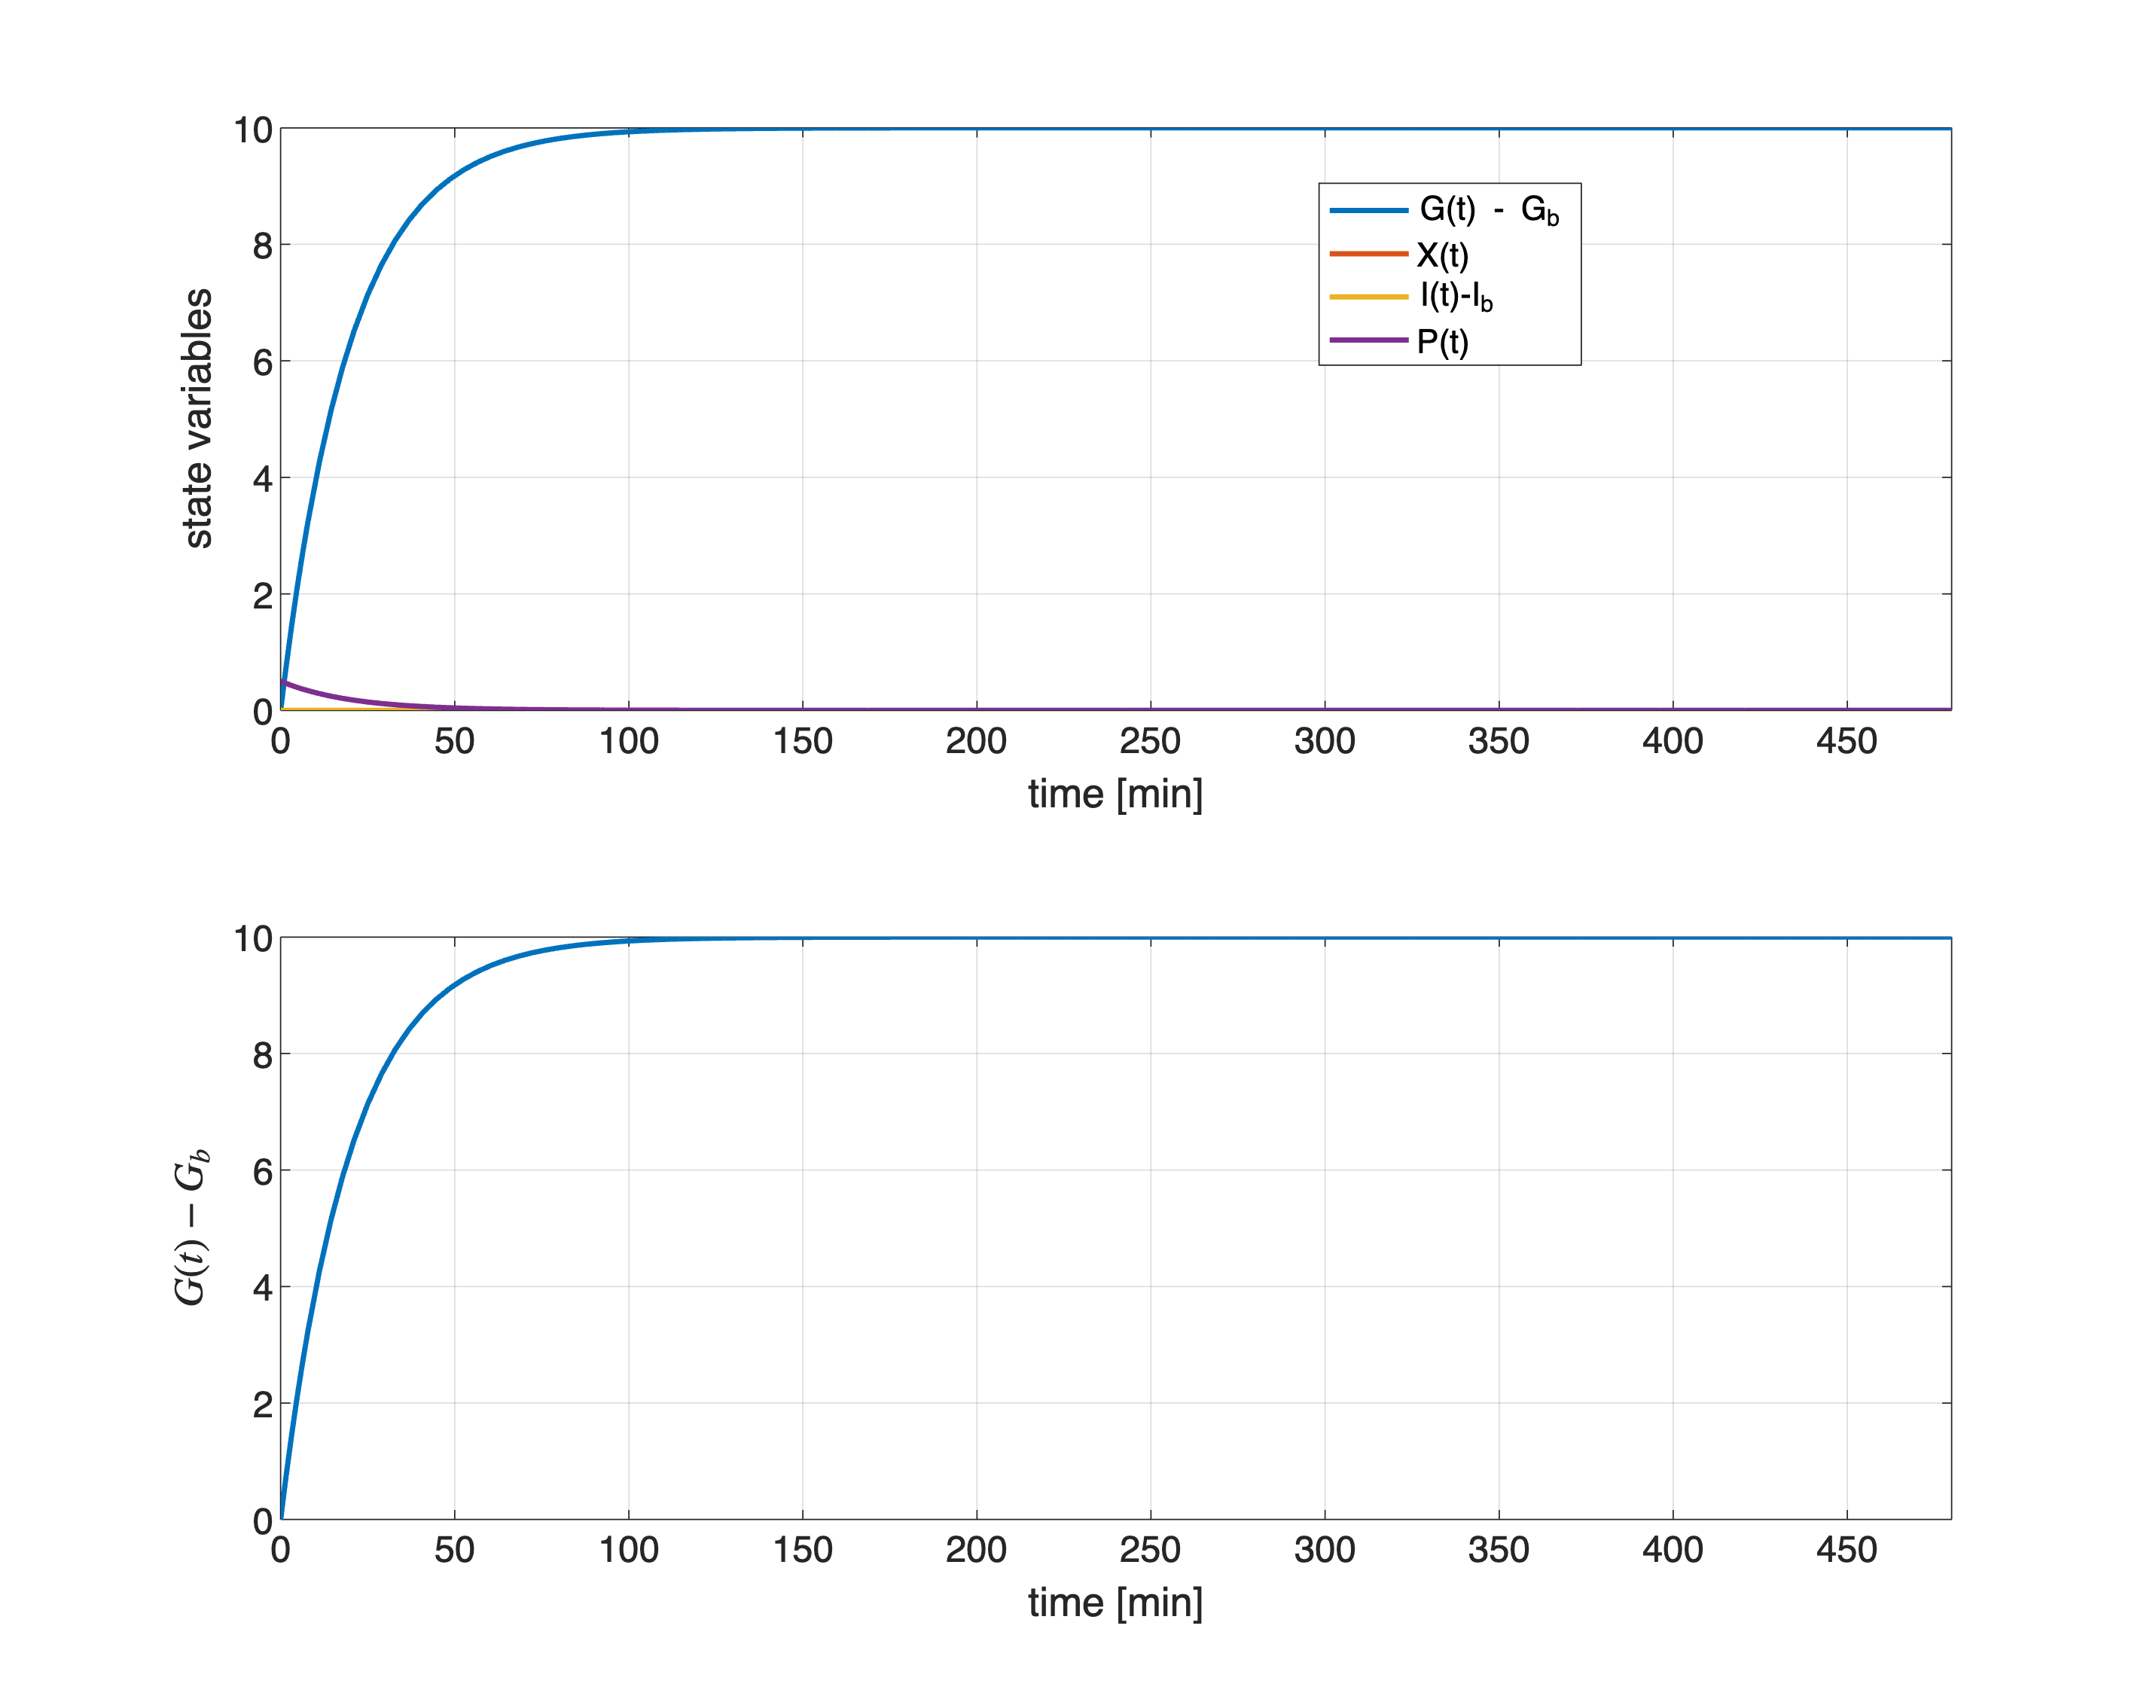

figure('Name','Double Pendulum Simulation','Units','normalized','Position',[0.1, 0.1, 0.75, 0.95]);
h1 = subplot(2,1,1);
plot(t_stamps, GlucIns_x1, 'LineWidth',2); % first state variable
hold on
plot(t_stamps, GlucIns_x2, 'LineWidth',2); % second state variable
plot(t_stamps, GlucIns_x3, 'LineWidth',2); % third state variable
plot(t_stamps, GlucIns_x4, 'LineWidth',2); % fourth state variable

xlabel('time [min]'); ylabel('state variables'); % labels on the plot axes
grid on; currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);
legend('G(t) - G_b', 'X(t)', 'I(t)-I_b', 'P(t)', 'Location', 'best')

h2 = subplot(2,1,2);
plot(t_stamps, y, 'LineWidth',2); % double pendulum outputs y_1 vs time
xlabel('time [min]'); ylabel('$G(t) - G_b$', 'Interpreter', 'latex'); % labels on the plot axes
grid on; 
currAX = axis(gca); currAX(1) = tMIN; currAX(2) = tMAX;
axis(currAX);set(gca, 'FontSize', 14);

linkaxes([h1 h2], 'x');

## References

[1] Antsaklis, Panos J..  * Linear systems / Panos J. Antsaklis, Anthony N. Michel.*. Boston, Birkhaeuser, 2006  

[2] Åström, Karl Johan, and Richard Murray. *Feedback systems: an introduction for scientists and engineers*. Princeton university press, 2021. [The electronic edition of Feedback Systems is available from [http://fbsbook.org]](about:blank<http://fbsbook.org]>)

[3] [https://web.mit.edu/jorloff/www/chaosTalk/double-pendulum/double-pendulum-en.html](https://web.mit.edu/jorloff/www/chaosTalk/double-pendulum/double-pendulum-en.html) 

[4] M. E. Fisher, "A semiclosed-loop algorithm for the control of blood glucose levels in diabetics," in *IEEE Transactions on Biomedical Engineering*, vol. 38, no. 1, pp. 57-61, Jan. 1991, doi: 10.1109/10.68209.

[5] F. Rahmanian, M. Dehghani, P. Karimaghaee, M. Mohammadi, R. Abolpour, "Hardware-in-the-loop control of glucose in diabetic patients based on nonlinear time-varying blood glucose model", *Biomedical Signal Processing and Control*, Volume 66, 2021, 102467, ISSN 1746-8094

## Summary

Using this live script you have learnt: 

- How to describe a nonlinear dynamic system in MATLAB;

- How to compute in MATLAB the free and the forced state and output movements for a nonlinear system.

#### Back to the Index

Use [this link](matlab:open('./usingMATLAB_034IN.mlx')) to go back to the main live script of the collection.

#### Back to the Previous Part: LTI Systems

Use [this link](matlab:open('./Intro_MATLAB_034IN_FAC_p6.mlx')) to go back to the previous live script of this collection.

## The Double Pendulum Model: The ODE as MATLAB Function

Let's define as a **MATLAB** **function** the first-order ODE system corresponding to


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=&  \displaystyle  x_2(t) \\ \\
\dot{x}_2(t) &=&   \displaystyle \frac{-g\left(2M_1+M_2\right)\sin x_1(t)-M_2\,g\sin \big(x(t)-2x_3(t) \big)-2M_2\sin\big(x_1(t)-x_3(t) \big) \cdot \left[ \left(x_4(t) \right)^2\cdot L_2 +  \left(x_2(t) \right)^2\cdot L_1 \cos\big(x_1(t) -x_3(t) \big)\right]  }{L_1 \Big[ 2M_1+M_2-M_2 \cos\Big( 2\big(x_1(t) - x_3(t) \big) \Big) \Big]} \\ \\
\dot{x}_3(t) &=&  \displaystyle x_4(t) \\ \\
\dot{x}_4(t) &=& \displaystyle \frac{2 \sin \big(x_1(t)-x_3(t) \big) \cdot \Big[ \left(x_2(t) \right)^2\cdot L_1 \left(M_1+M_2\right) +
g \left(M_1+M_2\right)\cos x_1(t) + \left(x_4(t) \right)^2 \cdot L_2\, M_2 \cos \big(x_1(t)-x_3(t) \big) \Big]}{L_2 \Big[ 2M_1+M_2-M_2 \cos\Big( 2\big(x_1(t) - x(t) \big)_3 \Big) \Big]}
\end{array} \right. \qquad (*)


$$


The MATLAB function must provide the first derivative vector $\big[ \dot{x}_1(t),\;\dot{x}_2(t), \;\dot{x}_3(t),\;\dot{x}_4(t) \big]^{\top}$, given the values of the variables $x_1,\,x_2,\,x_3$ and $x_4$ at the current time instant $t$ and the parameters' values.

% Define the function for the double pendulum ODEs
function dxdt = doublePEND_ODE(t, x, p)

    g  = p(1);
    L1 = p(2);
    L2 = p(3);
    m1 = p(4);
    m2 = p(5);
    % Unpack the state variables
    theta1 = x(1);
    omega1 = x(2);
    theta2 = x(3);
    omega2 = x(4);

    % Equations of motion for the double pendulum
    dxdt = zeros(4, 1);
    dxdt(1) = omega1;
    dxdt(2) = (-g * (2 * m1 + m2) * sin(theta1) - m2 * g * sin(theta1 - 2 * theta2) - 2 * sin(theta1 - theta2) * m2 * (omega2^2 * L2 + omega1^2 * L1 * cos(theta1 - theta2))) / (L1 * (2 * m1 + m2 - m2 * cos(2 * theta1 - 2 * theta2)));
    dxdt(3) = omega2;
    dxdt(4) = (2 * sin(theta1 - theta2) * (omega1^2 * L1 * (m1 + m2) + g * (m1 + m2) * cos(theta1) + omega2^2 * L2 * m2 * cos(theta1 - theta2))) / (L2 * (2 * m1 + m2 - m2 * cos(2 * theta1 - 2 * theta2)));
end


## The Glucose-Insuline Model: The ODE as MATLAB Function

Let's define as a **MATLAB** **function** the first-order ODE system corresponding to


$$\left\{ \begin{array}{rcl}
 \dot{x}_{1}(t) &=& -p_1\,x_{1}(t) -x_2(t)\,\big[x_{1}(t)+G_b \big] + x_4(t)    \\
\dot{x}_2(t) &=& -p_2\,x_2(t) + p_3\,x_{3}(t)\\
\dot{x}_{3}(t) &=& -n\big[x_{3}(t) + I_b \big] + \frac{u(t)}{V_I} \\
\dot{x}_4(t) &=& -k\,x_4(t)
\end{array} \right. \qquad (++)$$


The MATLAB function must provide the first derivative vector $\big[ \dot{x}_1(t),\;\dot{x}_2(t), \;\dot{x}_3(t),\;\dot{x}_4(t) \big]^{\top}$, given the values of the variables $x_1,\,x_2,\,x_3$ and $x_4$ at the current time instant $t$ and the parameters' values.

% Define the function for the double pendulum ODEs
function dxdt = GlucoseInsulineDYN_ODE(t, x, p)

    % GlucoseInsuline_ODE.Parameters   = [G_b, I_b, V_I, n, k, p1, p2, p3];  % the parameters of 
                                                                       % the differential equation
    G_b = p(1);
    I_b = p(2);
    V_I = p(3);
      n = p(4);
      k = p(5);
     p1 = p(6);
     p2 = p(7);
     p3 = p(8);
      u = p(9);
    % Unpack the state variables
    x1 = x(1);
    x2 = x(2);
    x3 = x(3);
    x4 = x(4);

    % glucose-insulin differential equations
    dxdt = zeros(4, 1);

    dxdt(1) = -p1*x1 -x2*(x1+G_b)+x4;
    dxdt(2) = -p2*x2+p3*x3;
    dxdt(3) = -n*(x3+I_b)+u/V_I;
    dxdt(4) = -k*x4;
end
